# JetBotをROSを使って遠隔操作し、学習画像収集

## 初期化

clear; close all; clc;

## JetBot上のROSノードを起動

ROS_MASTER_URI 環境変数の値 http://192.168.1.26:11311 は ROS マスターへの接続に使用されます。
NodeURI が http://192.168.1.18:53333/ のグローバル ノード /matlab_global_node_12264 を初期化中


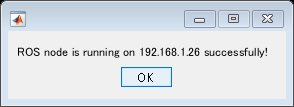

launchJetBotROSNode;

## JetBot上のROSに接続

rosshutdown;

NodeURI が http://192.168.1.18:53333/ のグローバル ノード /matlab_global_node_12264 をシャットダウン中


load('jetsonIpAddr.mat');
rosinit(jetsonIpAddr); 

NodeURI が http://192.168.1.18:53342/ のグローバル ノード /matlab_global_node_95370 を初期化中


## JetBotを制御する用のMATLABGUIを起動

**'s'キーでカメラ画像を動画として保存。**

jetBotKeyboardControl;

Keyboard Control: 
i=forward, k=backward, j=left, l=right
q=quit
Waiting for input: 


## JetBotを制御する用のSimulinkモデルを起動

open_system('ros_teleop');

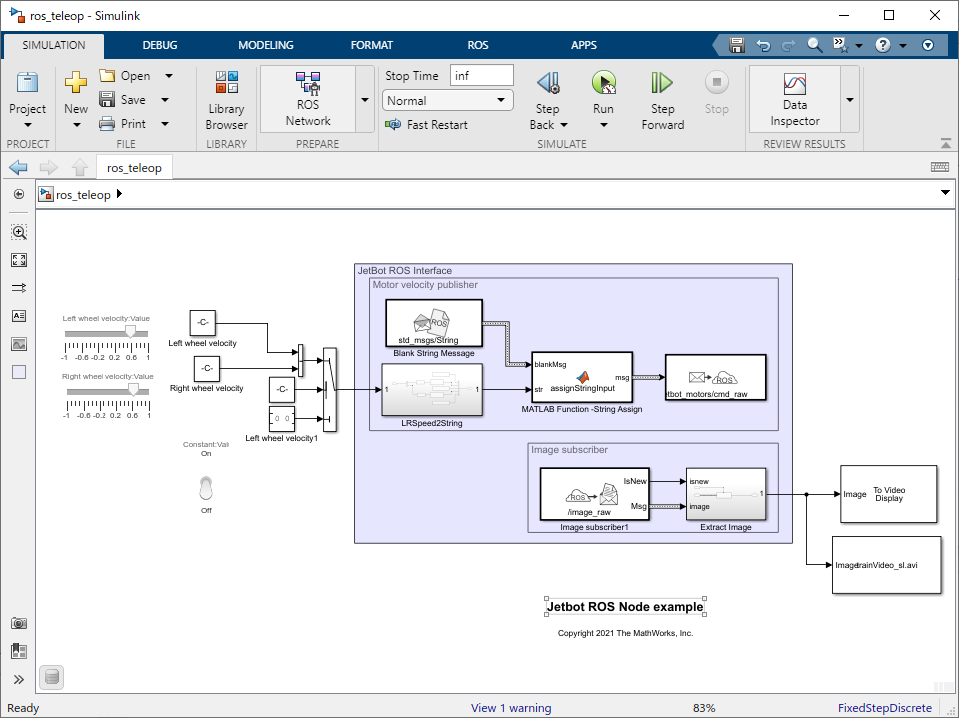

「シミュレーション」タブの「ROSネットワーク」を選択し、「ネットワークアドレス」を「カスタム」に変更、さらに「ホスト名/IPアドレス」を接続先のJetBotのIPアドレスに変更する

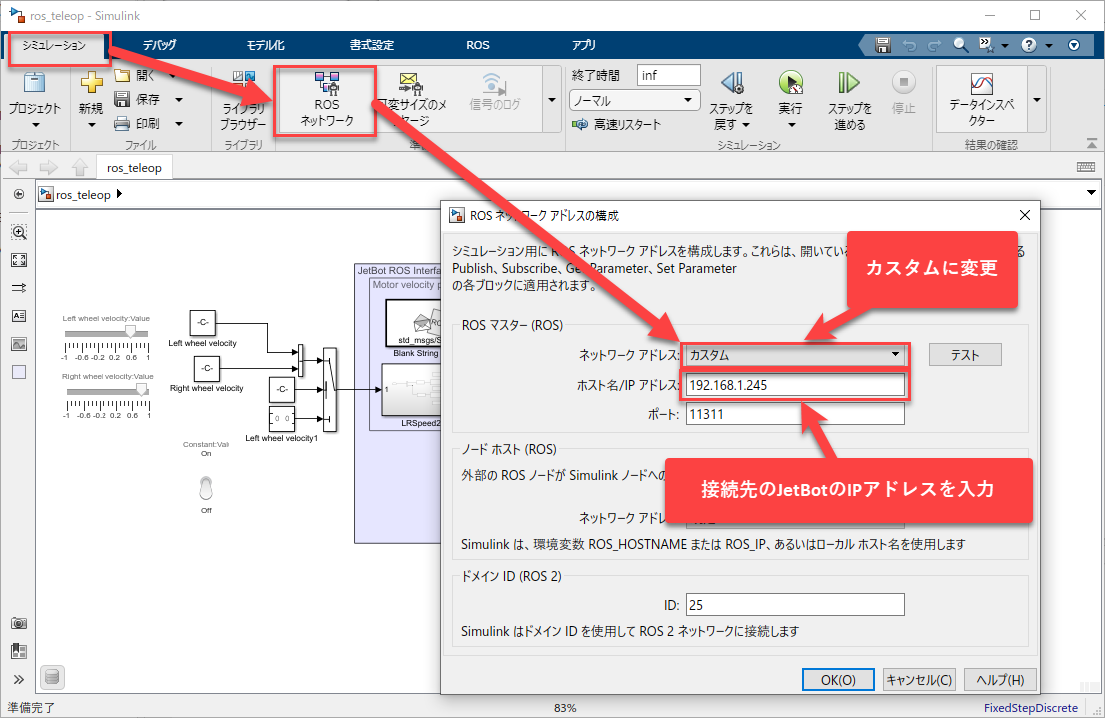

## ROS接続を切断

rosshutdown

NodeURI が http://192.168.1.18:53342/ のグローバル ノード /matlab_global_node_95370 をシャットダウン中


## JetBot上のROSノードを停止

stopJetBotROSNode;

*Copyright 2021 The MathWorks, Inc.*